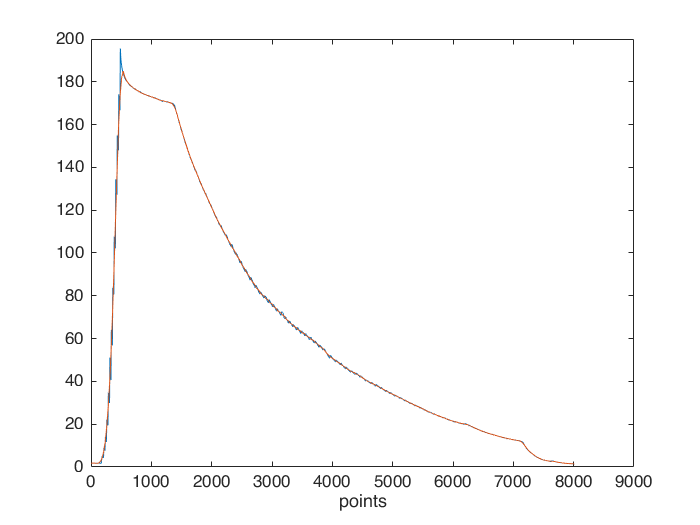

data = readmatrix('yusuf2.csv');
d_mean = movmean(data,100);

plot(data)
hold on
plot(d_mean)
hold off
xlabel("points")

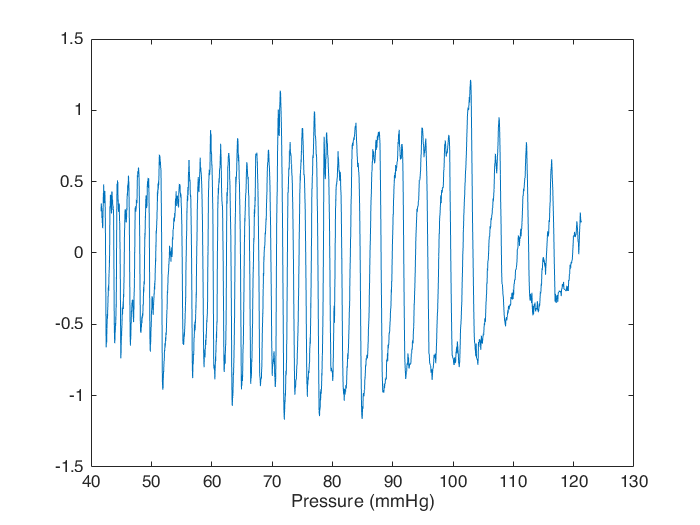



osc = data - d_mean;
plot(d_mean(2000:4500), osc(2000:4500))
xlabel("Pressure (mmHg)")

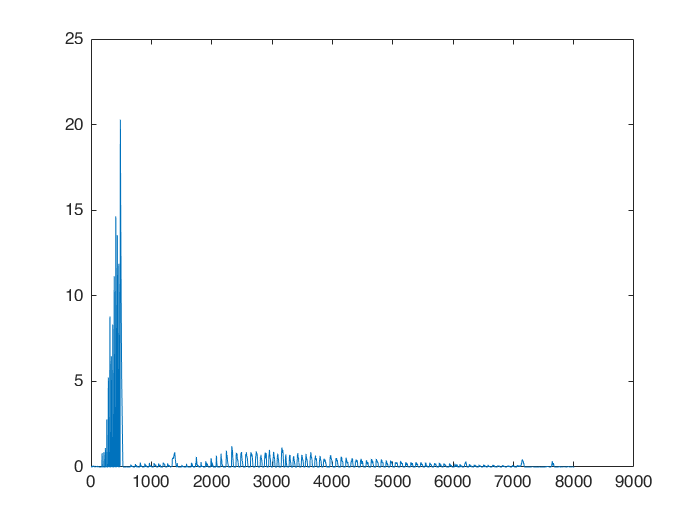



pos_osc = max(osc,0);
plot(pos_osc)

plot_osc = bandpass(pos_osc, [0.5 5],100)

plot_osc =    -0.1995   -0.1686   -0.1405   -0.1163   -0.0970   -0.0834   -0.0758   -0.0745   -0.0790   -0.0888   -0.1028   -0.1197   -0.1381   -0.1565   -0.1735   -0.1879   -0.1989   -0.2059   -0.2087   -0.2076   -0.2032   -0.1962   -0.1878   -0.1789   -0.1706   -0.1639   -0.1593   -0.1572   -0.1577   -0.1605   -0.1651   -0.1708   -0.1766   -0.1818   -0.1855   -0.1869   -0.1857   -0.1816   -0.1746   -0.1652   -0.1540   -0.1416   -0.1289   -0.1169   -0.1062   -0.0976   -0.0915   -0.0881   -0.0873   -0.0888


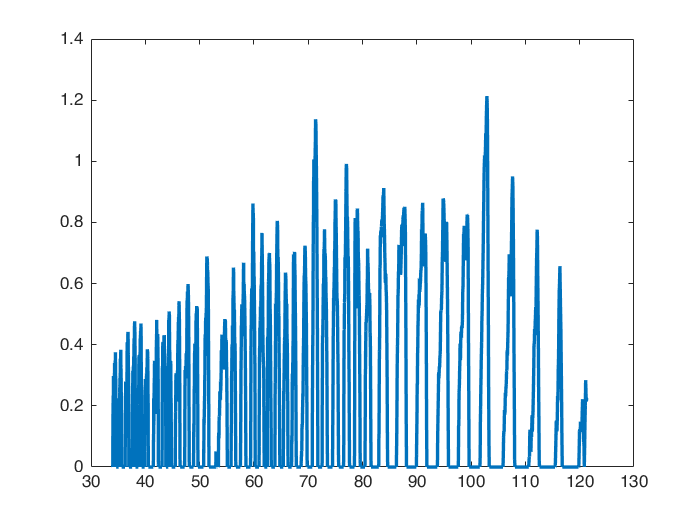

plot(d_mean(2000:5000),pos_osc(2000:5000), "LineWidth", 2)

%xlim([0 3500])

data = readmatrix('data.csv');
data = diff(data);
avg = mean(data)